## Composing 2-D Transformations

clear all; close all;

## Transformations

Scaling

S = [ 2 0;
      0 3 ];
  

% Rotation
theta = pi/4; 
R = [ cos(theta) -sin(theta);
      sin(theta)  cos(theta) ];

## The shape to be transformed

Rectangle given by four vertices

px = [0 1 1 0];   % x-coords
py = [0 0 1 1];   % y-coords  
disp('Input shape')

Input shape


X  = [px;py]        % Matrix containing the 2-D points.

X =      0     1     1     0
     0     0     1     1


## Apply transformation to shape

X_p = (R * S) * X 

X_p =          0    1.4142   -0.7071   -2.1213
         0    1.4142    3.5355    2.1213


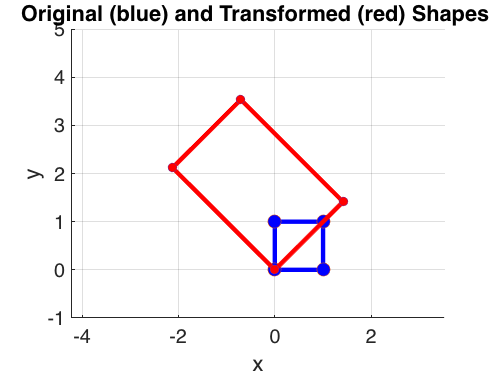


showShapes(X,X_p)

## Apply transformation to shape

X_p = (S * R) * X 

X_p =          0    1.4142    0.0000   -1.4142
         0    2.1213    4.2426    2.1213


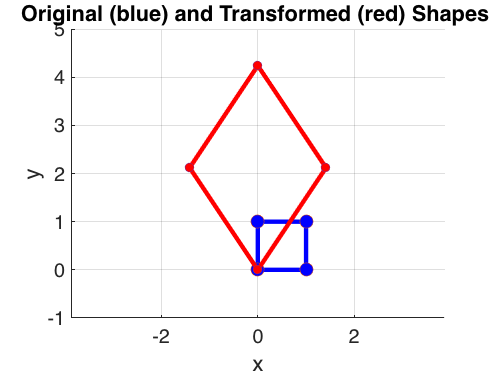


showShapes(X,X_p)

## Display shapes

function showShapes(X,X_p)
figure;
hold on;
axis([ -3 4 -1 5 ] );
% Repeating the first vertex to close polygon lines
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'b-', 'linewidth',4);
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'o', 'MarkerSize', 12, 'MarkerFaceColor','b')
xlabel('x','FontSize',30);
ylabel('y','FontSize',30);
set(gca, 'fontsize',18);
set(gcf, 'color', 'w' );
title('Original (blue) and Transformed (red) Shapes ');
% Show the transformed points
plt = plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'r-', 'linewidth',4);
plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','r');
% Plot transformed shape transparent
plt.Color(4) = 0.5;
axis equal
grid on;
end
